# MAE384 Group Project

Initialize common variables and functions:

% Beta is the Transmission Rate
% Gamma is the Recovery Rate
% S(t) is # of Susceptible Individuals at t
% I(t) is # of Infected Individuals at t
% R(t) is # of Recovered Individuals at t
dSdt = @(S,I,R,beta) (-beta./(S+I+R)).*S.*I;
dIdt = @(S,I,R,beta,gamma) (beta./(S+I+R)).*S.*I - gamma.*I;
dRdt = @(I,gamma) gamma.*I;
N = S + I + R;

# Part 1. Runge-Kutta

## 1.

%Parameters
h1 = 1; %Time step; Days
t0 = 0; %Initial Time
s0 = 990; %Initial Susceptible Indiviudals
i0 = 10; %Initial Infected Individuals
r0 = 0; %Initial Recovered Individuals
T = 100; %Total Simulation Time, Days
betaFlu = 0.3;
gammaFlu = 0.1;
betaCovid = 1;
gammaCovid = 0.1;
betaMeas = 2;
gammaMeas = 0.2;

Flu = [0.3,0.1]; %Beta,Gamma
Covid = [1,0.1]; %Beta,Gamma
Meas = [2,0.2]; %Beta,Gamma
Dis = [Flu;Covid;Meas];


%Solving
t1 = 0; %Time variable part 1, days
N = (T - t0)/h1; %Number of Steps
S = zeros(3,N+1);
S(:,1) = s0;
I = zeros(3,N+1);
I(:,1) = i0;
R = zeros(3,N+1);
R(:,1) = r0;
for k = 1:3
    beta(k) = Dis(k,1);
    gamma(k) = Dis(k,2);
    for i = 1:N
        k1 = SIRModel(S(k,i),I(k,i),R(k,i),beta(k),gamma(k));
        k2 = SIRModel(S(k,i) + 0.5*h1*k1(1),I(k,i) + 0.5*h1*k1(2),R(k,i) + 0.5*h1*k1(3),beta(k),gamma(k));
        k3 = SIRModel(S(k,i) + 0.5*h1*k2(1),I(k,i) + 0.5*h1*k2(2),R(k,i) + 0.5*h1*k2(3),beta(k),gamma(k));
        k4 = SIRModel(S(k,i) + h1*k3(1),I(k,i) + h1*k3(2),R(k,i) + h1*k3(3),beta(k),gamma(k));
        S(k,i+1) = S(k,i) + (1/6)*(k1(1) + 2*k2(1) + 2*k3(1) + k4(1))*h1;
        I(k,i+1) = I(k,i) + (1/6)*(k1(2) + 2*k2(2) + 2*k3(2) + k4(2))*h1;
        R(k,i+1) = R(k,i) + (1/6)*(k1(3) +2*k2(3) + 2*k3(3) + k4(3))*h1;
    end
end

## 2.

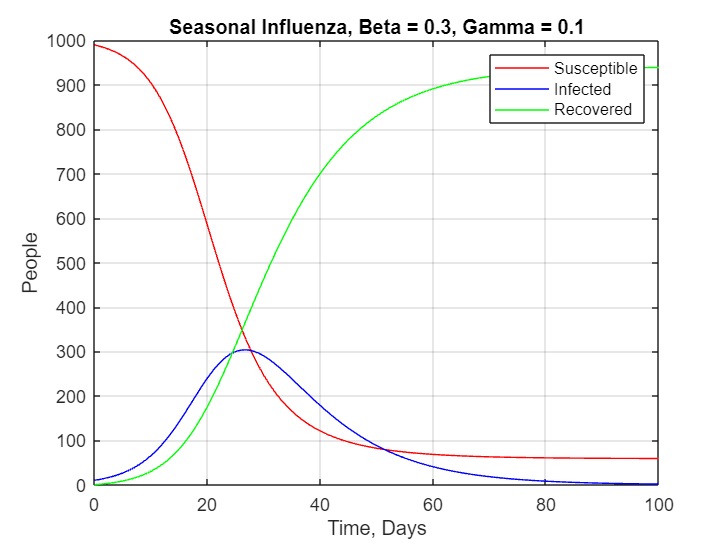

t = 0:100;
%Flu
plot(t,S(1,:),'r',t,I(1,:),'b',t,R(1,:),'g')
hold on;
grid on;
title('Seasonal Influenza, Beta = 0.3, Gamma = 0.1');
xlabel('Time, Days');
ylabel('People');
legend('Susceptible','Infected','Recovered');
hold off;

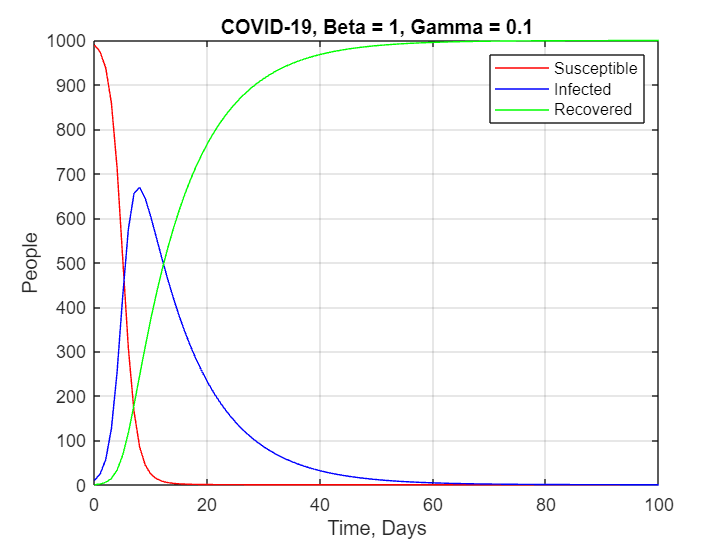


%Covid-19
plot(t,S(2,:),'r',t,I(2,:),'b',t,R(2,:),'g')
hold on;
grid on;
title('COVID-19, Beta = 1, Gamma = 0.1');
xlabel('Time, Days');
ylabel('People');
legend('Susceptible','Infected','Recovered');
hold off;

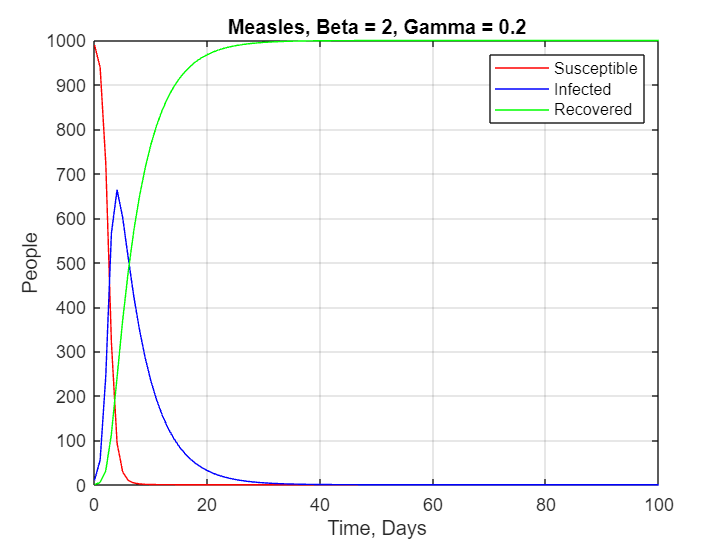


%Measles
plot(t,S(3,:),'r',t,I(3,:),'b',t,R(3,:),'g')
hold on;
grid on;
title('Measles, Beta = 2, Gamma = 0.2');
xlabel('Time, Days');
ylabel('People');
legend('Susceptible','Infected','Recovered');
hold off;